close all; clear; clc;

# Name/Purpose of Test

**filename**: ramp_20180628.mlx

**keywords:** 

**file created by:** {20180629, NAME}

**last updated on:** {20180629}

**primary purpose:** {Enter the primary purpose and primary input and output variables.}

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** [C_T], [C_P], [C_Q]

**Notes:** Rotational Speed was calculated in RPM, needed to convert to rad/sec.

I don't think I tore the voltage or load cell before recording the data.

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.002285947263;                  % [slugs/ft^3]

% Motor Specs
radius = 7.5/12;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data

load('RampTest.mat');
time = RampTest(:,1);          % [sec]
ESC_us = RampTest(:,2);        % [micro sec] (this is how quickly the ESC is providing voltage to the motor -- translates to throttle% ?
Q = RampTest(:,3);             % [ft.lbf]
T = RampTest(:,4);             % [lbf]
Input_V = RampTest(:,5);       % [Volts]
Input_A = RampTest(:,6);       % [Amps]
rot_speedRPM = RampTest(:,7);     % [RPM]
% Convert RPM to rad/sec
rot_speed = rot_speedRPM .* (pi/30);

P_in_W = RampTest(:,8);        % [Watts]
P_out_W = RampTest(:,9);        % [Watts]
% convert to [ft.lbf/sec]
P_out = P_out_W .* 0.7478;     % [ft.lbf/sec]         
P_in = P_in_W .* 0.7478;       % [ft.lbf/sec]

Motor_Eff = RampTest(:,10);    % [%]
Prop_Eff = RampTest(:,11);     % [lbf/Watts]
Overall_Eff = RampTest(:,12);  % [lbf/Watts]  
Motor_Temp = RampTest(:,13);   % [F]


## Thrust, Power, and Torque Coefficents

[C_T] = Thrust_Coefficient(T,p,area,rot_speed,radius);
[C_P] = Power_Coefficient(P_out,p,area,rot_speed,radius);
[C_Q] = Torque_Coefficient(Q,p,area,rot_speed,radius);

## Plots

{This is the section for generating output tables, plots, etc.}

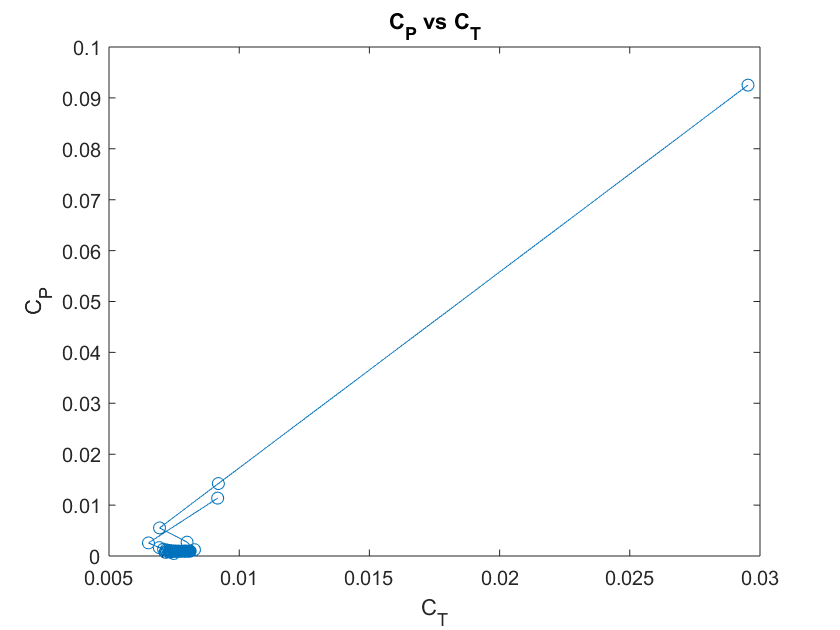


figure(1)
plot(C_T, C_P,'o-');
title('C_P vs C_T'); xlabel('C_T'); ylabel('C_P')

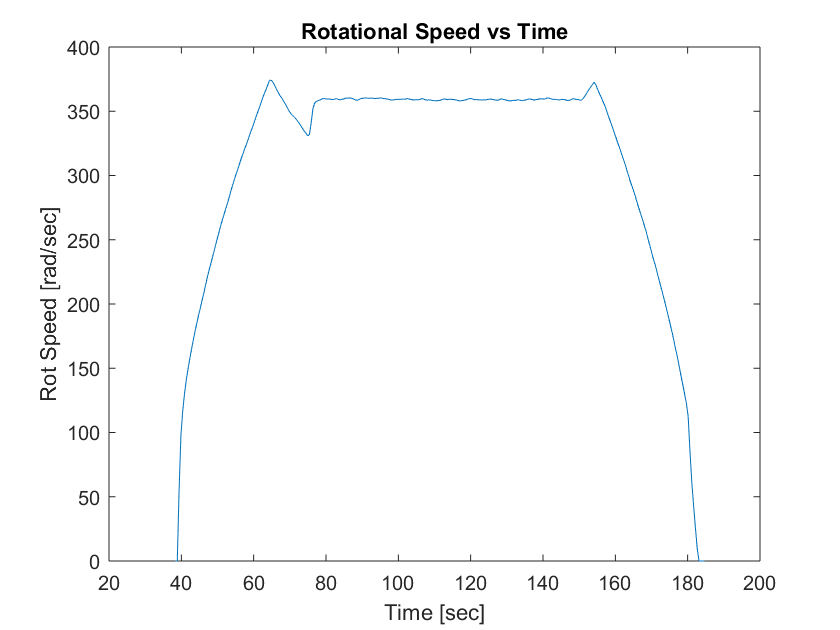

figure(2)
plot(time, rot_speed);
title('Rotational Speed vs Time'); xlabel('Time [sec]'); ylabel('Rot Speed [rad/sec]')

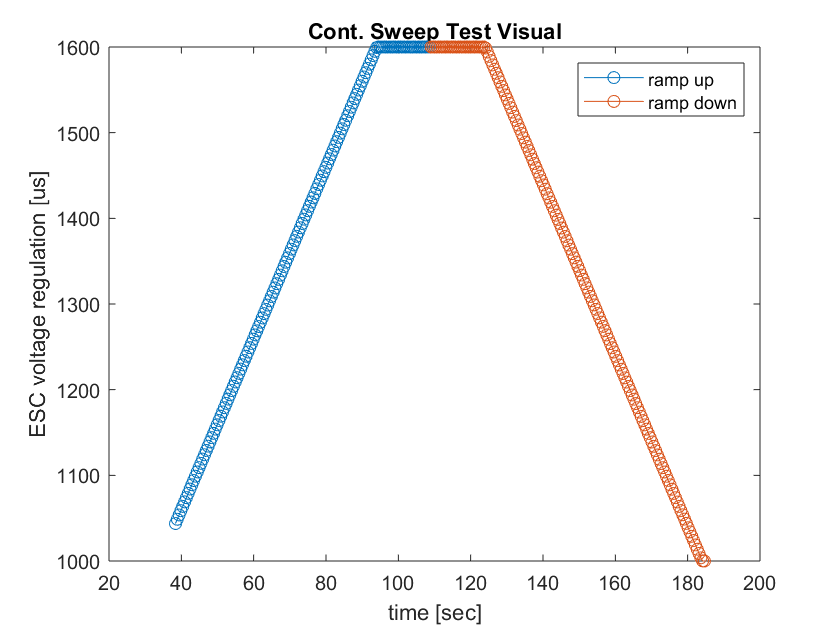

x = (1:142);
y = (142:293);
figure(3)
plot(time(x), ESC_us(x),'o-',time(y), ESC_us(y), 'o-');
title('Cont. Sweep Test Visual'); xlabel('time [sec]'); ylabel('ESC voltage regulation [us]')
legend('ramp up','ramp down')

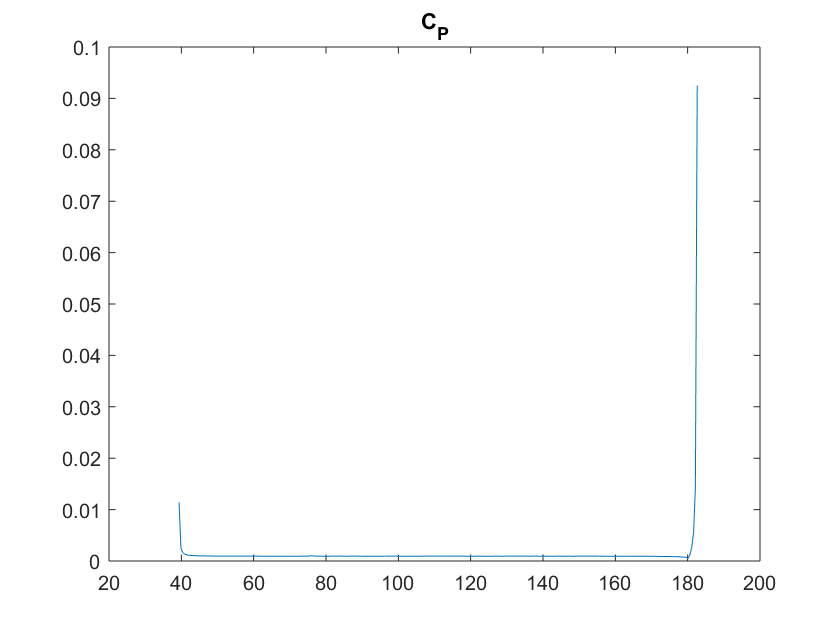




figure(4)
plot(time, C_P);
title('C_P');

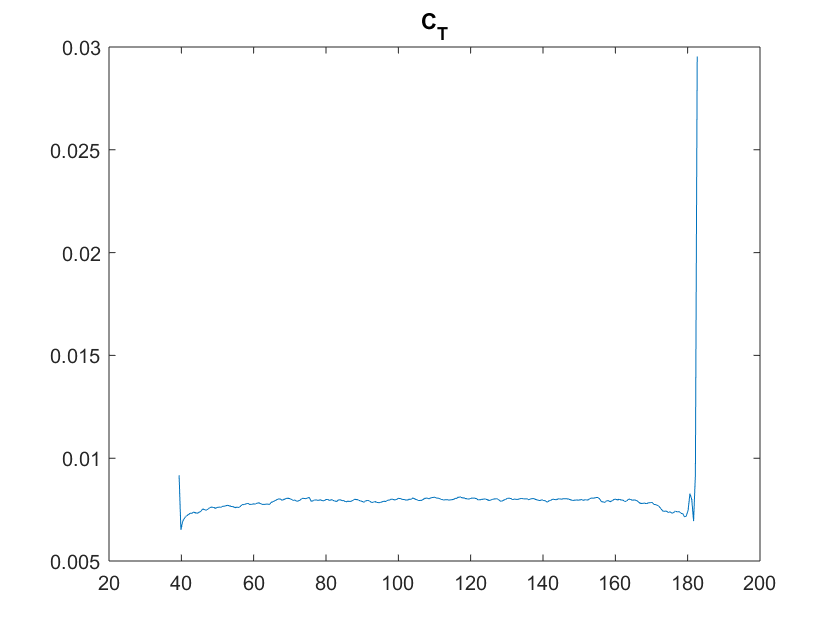


figure(5)
plot(time, C_T);
title('C_T');

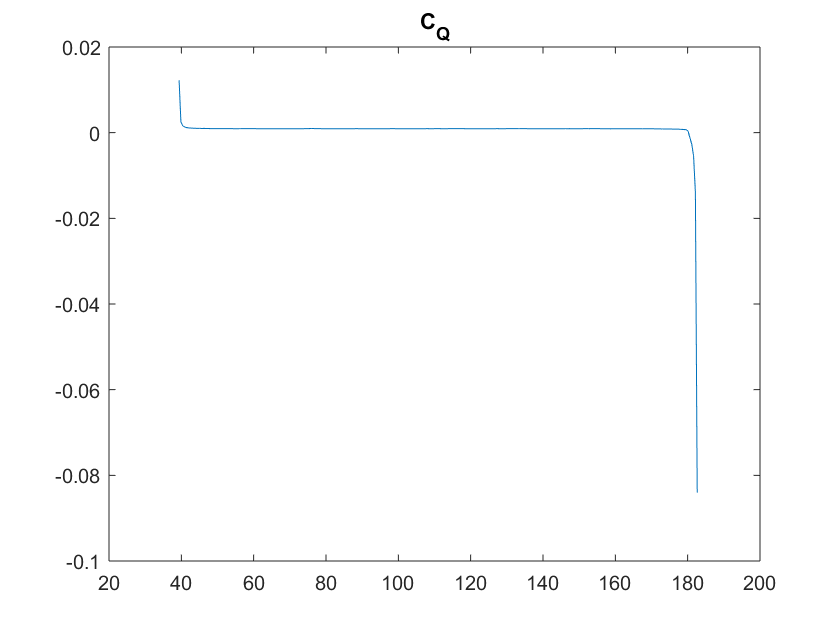


figure(6)
plot(time, C_Q);
title('C_Q');

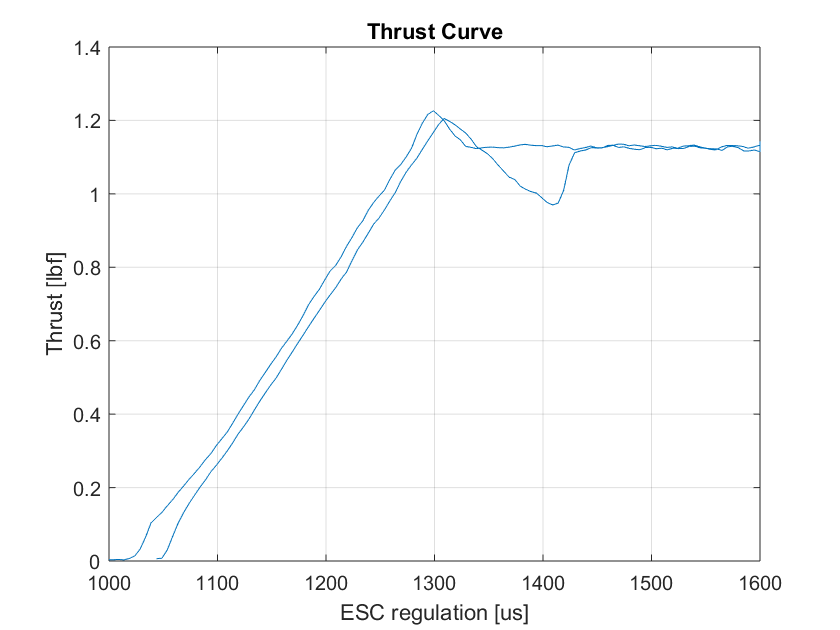

figure(7)
plot(ESC_us, T);
title('Thrust Curve'); xlabel('ESC regulation [us]'); ylabel('Thrust [lbf]'); 
grid('on'); ylim([0,1.4]);